clear
clc

loadSim

Loading file: D05_08_h05_Ed_Asbc_R01
Loading file: D05_08_h05_Ef_Ab_03H01_R01
Loading file: D05_08_h05_Ef_Asbc_R01
Loading file: D05_13_h05_Ef_An_R01
Loading file: D05_13_h05_Ef_An_R02
Loading file: D06_05_h05_Ea_An00H00_R01
Loading file: D06_05_h05_Eb_An00H00_R01
Loading file: D06_05_h05_Ed_As10H05_R01
Loading file: D06_05_h05_Ef_Ab05H02_R01
Loading file: D06_05_h05_Ef_Ab05H05_R01
Loading file: D06_05_h05_Ef_Ac05H0108_R01
Loading file: D06_05_h05_Ef_Ac08H0108_R01
Loading file: D06_05_h05_Ef_As03H02_R01
Loading file: D06_05_h05_Ef_As03H05_R01
Loading file: D06_05_h05_Ef_As03H10_R01
Loading file: D06_05_h05_Ef_As05H05_R01
Loading file: D06_05_h05_Ef_As07H02_R01
Loading file: D06_05_h05_Ef_As10H05_R01
Loading file: DC_bias
Elapsed time is 0.082211 seconds.
Data loaded


DC = mean(DC_bias.data(:,4))

DC = 0.0863


y = D05_08_h05_Ef_Asbc_R01.data(:,2:3);
u = D05_08_h05_Ef_Asbc_R01.data(:,4)-DC;
z1 = iddata(y, u, 0.05, 'Name', 'Pendulum');
z1.OutputName = {'Pendulum position','Flywheel angular velocity'};
z1.OutputUnit = {'rad','rad/s'};
z1.InputName = {'Control Signal'};
z1.Tstart = 0;
z1.TimeUnit = 's';

y = D05_08_h05_Ef_Asbc_R01.data(:,2:3);
u = D05_08_h05_Ef_Asbc_R01.data(:,4)-DC;
z2 = iddata(y, u, 0.05, 'Name', 'Pendulum');
z2.OutputName = {'Pendulum position','Flywheel angular velocity'};
z2.OutputUnit = {'rad','rad/s'};
z2.InputName = {'Control Signal'};
z2.Tstart = 0;
z2.TimeUnit = 's';

FileName      = 'flywheel_extended';        % File describing the model structure.
Order         = [2 1 3];             % Model orders [ny nu nx].
Parameters    = [100; 0.2; 1e-4; 100; 0.1];  
InitialStates = [0; 0; 0];              % Initial initial states.
Ts            = 0;                   % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);
nlgr.OutputName = {'Pendulum position','Flywheel angular velocity'};
nlgr.OutputUnit = {'rad','rad/s'};
nlgr.TimeUnit = 's';
nlgr = setinit(nlgr, 'Name', {'Pendulum position' 'Pendulum velocity' 'Flywheel velocity'});
nlgr = setinit(nlgr, 'Unit', {'rad' 'rad/s' 'rad/s'});
nlgr = setpar(nlgr, 'Name', {'K1' 'K2' 'K3' 'K4' 'K5'});
nlgr = setpar(nlgr, 'Unit', {'idk' 'idk' 'idk' 'idk' 'idk'});
nlgr = setpar(nlgr, 'Minimum', {-inf -inf -inf -inf -inf});   % All parameters > 0.
nlgr = setpar(nlgr, 'Maximum', {inf inf inf inf inf});   % All parameters > 0.


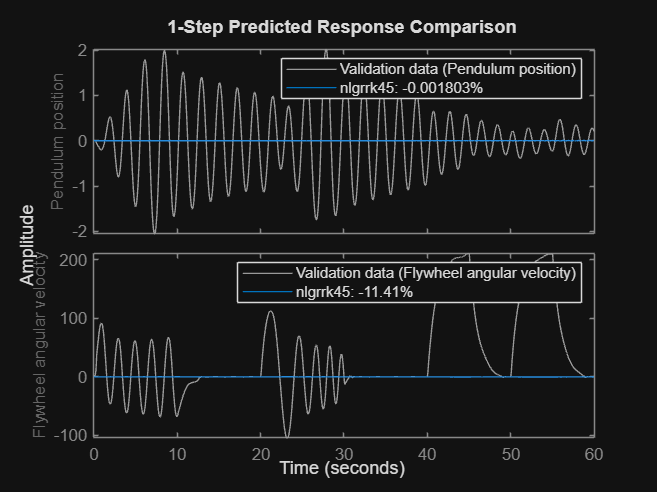

nlgrrk45 = nlgr;
nlgrrk45.SimulationOptions.Solver = 'ode45';     % Runge-Kutta 45.

compare(z2, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

nlgrrk45 = setpar(nlgrrk45, 'Fixed', {false false false false false});

We finally use the Runge-Kutta 45 solver (ode45).

opt = nlgreyestOptions('Display', 'on');
opt.OutputWeight = [1000,0;0,1];
nlgrrk45 = nlgreyest(z2, nlgrrk45, opt)   % Perform parameter estimation.

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p5)
    y(t) = H(t, u(t), x(t), p1, ..., p5) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 5 free parameter(s) (out of 5).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-25.09;47.95]%                                         
FPE: 1484, MSE: 1504                                                            

Model Properties


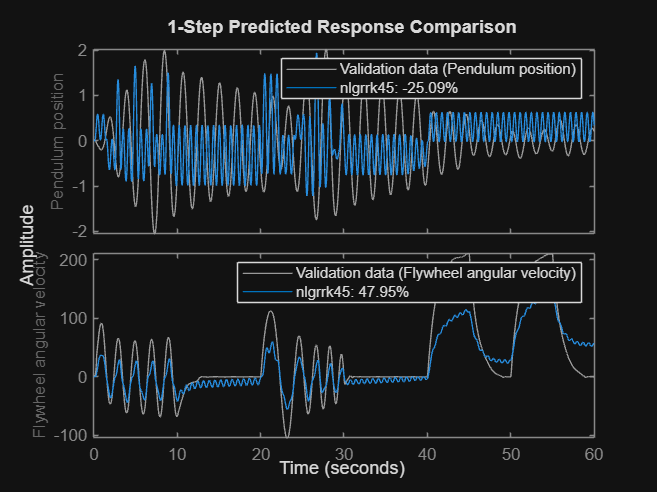

compare(z2, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

fpe(nlgrrk45);

   1.4837e+03






for i = 1:4 
    opt.OutputWeight = [10000,0;0,1];
    nlgrrk45 = nlgreyest(z1,nlgrrk45, opt)
    nlgrrk45 = pem(z2,nlgrrk45, opt)
    nlgrrk45 = nlgreyest(z2,nlgrrk45, opt)
    nlgrrk45 = pem(z1,nlgrrk45, opt)
    
    nlgrrk45.Parameters
    figure(i),clf;
        compare(z1, nlgrrk45, 1, ...
        compareOptions('InitialCondition', 'model'));
end